# Discrete Cosine Transform

### ### Insert Name ###

## Display Blocks 

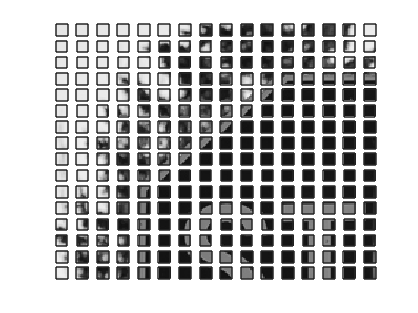

% Displays the upper left 128 by 128 pixels of an image as a matrix of
% sixteen by sixteen 8 by 8 blocks

%% Set up workspace
close all
clear

load stop.mat  % file containing image stop
im = stop;

[M,N] = size(im);

C_im = [0,255]; % maintain image dynamic range for all blocks

%% 

figure
for i=1:min(16, round(M/8))
    for j=1:min(16, round(N/8))
        nrange = (i-1)*8+1:(i-1)*8+8;
        mrange = (j-1)*8+1:(j-1)*8+8;
        block = im(nrange,mrange); 
        subplot(16,16,j+(i-1)*16)
        imagesc(block,C_im)
        colormap(gray)
        set(gca,'Xtick',[])
        set(gca,'Ytick',[])
        axis('square')
    end
end

k=5

k = 5

fhat = k/20

fhat = 0.2500

Y = (1 + exp(1j*2*pi*fhat*-2))

Y = 0.0000e+00 - 1.2246e-16i


real(Y)

ans = 0

imag(Y)

ans = -1.2246e-16

## The (1,1) block

% Your code here

B1_1 = DCTBlock(im, 1, 1)

k = 1

fhat = 0.0500

Y = 17.0259 - 0.5878i

ans = 17.0259

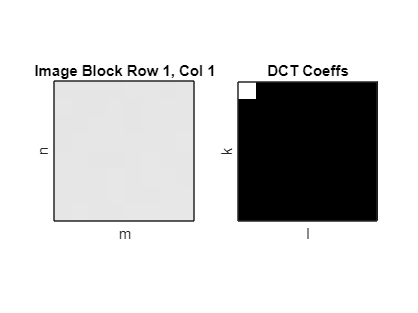

B1_1 = 1.0e+03 *

    1.8399   -0.0022    0.0002    0.0002   -0.0001    0.0000    0.0001   -0.0009
   -0.0032   -0.0000   -0.0000   -0.0001    0.0004    0.0000    0.0009   -0.0000
    0.0002   -0.0000    0.0000    0.0001    0.0004   -0.0002   -0.0002    0.0002
   -0.0003    0.0002   -0.0002    0.0009    0.0002    0.0001    0.0001   -0.0002
   -0.0001   -0.0002    0.0002    0.0006   -0.0001   -0.0020    0.0001    0.0005
   -0.0000   -0.0003   -0.0004   -0.0014    0.0003   -0.0001   -0.0001    0.0002
    0.0001   -0.0000   -0.0007    0.0001   -0.0006   -0.0001    0.0002    0.0001
   -0.0008    0.0000    0.0002    0.0004   -0.0001   -0.0002    0.0003    0.0001


B1_1(1,1)


[test_1] = DCT_Thresh(B1_1, .01*B1_1(1,1))

## The (8,3) block

% Your code here

ans = 1.8399e+03

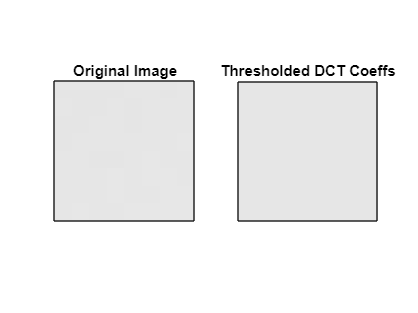

test_1 = 1.0e+03 *

    1.8399         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0



B8_3 = DCTBlock(im, 8, 3)

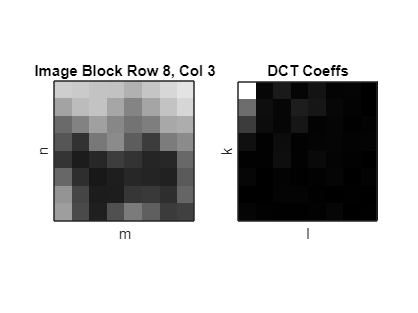

B8_3 =   872.8750  -25.5364   91.1059  -18.2606   65.1250   15.1164   18.4118    0.0553
  375.0200  -51.1474  -20.6394  -99.3049  -77.2853   24.0227  -10.8573   -0.3596
  205.0646   43.7102   22.4805   75.0709  -11.2131  -20.1232   -4.7164  -11.8781
  -56.7386    8.9964   42.3029    7.7702   14.7854  -20.1351   11.6962  -14.5504
    6.8750   -8.6758  -50.2622   10.0728   32.1250   15.9223   -7.9994    2.4620
   20.9730   -0.9722   12.8726   -4.1728    8.5093   18.0223    0.4627   11.8113
    1.5155   -1.1267  -15.9664   16.1361   -3.8792   -3.4122   -5.9805    2.7983
  -19.6760   -8.8973    6.2800    5.6623   -8.6038  -20.7823    2.9698   -6.1451


[test_2] = DCT_Thresh(B8_3, .05*B8_3(1,1))

## The (15,13) block

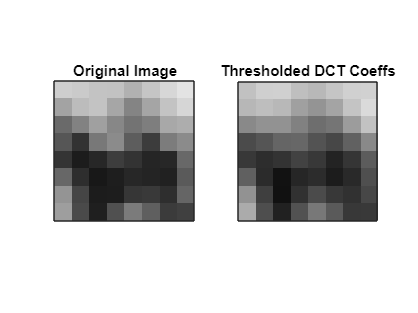

test_2 =   872.8750         0   91.1059         0   65.1250         0         0         0
  375.0200  -51.1474         0  -99.3049  -77.2853         0         0         0
  205.0646   43.7102         0   75.0709         0         0         0         0
  -56.7386         0         0         0         0         0         0         0
         0         0  -50.2622         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0


% Your code here

B15_13 = DCTBlock(im, 15, 13)

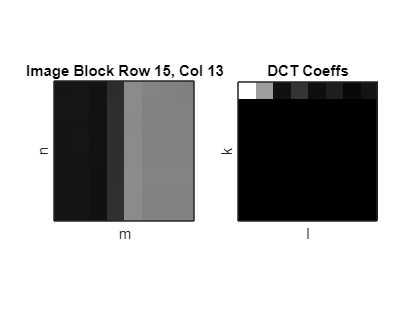

B15_13 =   635.1250 -391.5841  -44.0385  131.2245   37.3750  -74.6973  -23.0249   50.8457
   -0.4423    1.0877    1.2433    0.5012   -2.0934   -0.9829    0.7629    1.2632
   -0.8562    1.3008   -0.9937    1.0993   -0.2590    0.0976   -0.1616   -0.4763
    1.0058   -1.0711   -0.1980    0.9408   -0.5292   -0.0138   -0.4625    0.5318
   -0.1250    0.2371   -0.2590    0.0718   -0.8750   -0.0143   -0.2986    0.3549
   -0.3803   -0.1050   -0.0986    0.1327   -0.6285   -0.1908   -0.1602   -0.0837
    0.2194   -1.4009    0.3384    0.1295   -0.2986   -0.0425    0.2437    0.0830
   -0.9801    0.4096   -0.3902   -0.5045    0.0715    0.5744    0.5538   -0.3377


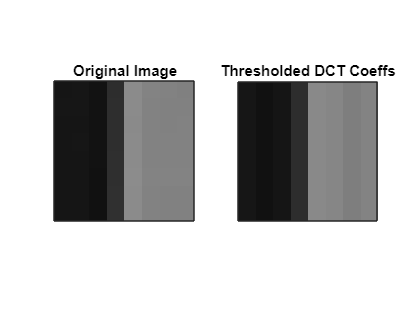

test_3 =   635.1250 -391.5841  -44.0385  131.2245   37.3750  -74.6973         0   50.8457
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0


[test_3] = DCT_Thresh(B15_13, .05*B15_13(1,1))